Jeremy Primus

MECH532

Final Exam

2.

% initialization
clear all
P = 30.5e3;         % load
ac = 52e-3;         % crack length @ failure
E = 210e9;          % elastic modulus
nu = 0.3;           % Poisson's ratio
sigma_ys = 350e6;   % yield strength
sigma_uts = 500e6;  % ultimate tensile strength
W = 100e-3;         % width
B = 25e-3;          % thickness
phi = 25e-3;        % grip hole diameter
C = 25e-3;          % grip hole to edge
d = 27.5e-3;        % grip hole to crack


mode I loading

a) Kcrit value:

Kcrit = (P*(2+ac/W)/(B*sqrt(W)*(1-ac/W)^1.5))*(0.76 + 4.8*(ac/W) - 11.58*(ac/W)^2 + 11.43*(ac/W)^3 - 4.08*(ac/W)^4);   % KI at fracture
disp({num2str(Kcrit/1e6), 'MPa m^0.5'})

    '41.911'    'MPa m^0.5'



b)

Plastic zone radius:

r_y = (1/(2*pi)*(Kcrit/sigma_ys)^2) 

r_y = 0.0023

Gcrit value:

Gcrit = -(Kcrit*2*sqrt(ac)*P/(E*(W-ac)))*(ac/(W-ac) + 1)

Gcrit = -120.4917

The units here should be J/m^2.  However, I obtain N for my units, so it seems I should have another length factor in the denominator.  Can't find the mistake.

r_y <= (B/15)

ans = logical
   0


c)

r_y <= (B/15)

ans = logical
   0


given that this conditional statement is false, the part does not satisfy plane strain conditions, and  $K_I \not= K_{\mathrm{IC}}$ at fracture.  This the K value at fracture is Kcrit, and we expect there to be a crack size dependent toughess, or a resistance curve.  In order to obtain K1c, the speciment would need to have a minimum thickness of:

Bmin = 15*r_y

Bmin = 0.0342

The thickness of the disk must be 35mm or more to satisfy plane strain conditions and measure K1c at fracture

d) Put the specimen in displacement control.  Set the displacement, letting the crack grow stabily and then cease growing, then unload.  The slope of unloading will give compliance.  From a measurement of compliance, we can obtain strain energy release rate, at the given crack size.  We can continually do this, increasing the crack size to obtain an R curve behavior.  The R curve is a material property characterizing crack growth behavior dependent on crack size.

3.

% initialization 
sigma_ys = 880e6;
sigma_uts = 950e6;
RA = 0.36;
nu = 0.34;
sigma_f = 510e6;  % in Pa
E = 114e9;
Kic = 75e6;
ao = 0.5e-3;
R = 1.5;
t = 0.05;
L = 5;
Nf = 10^7;
A = 1e-11;
m = 3.2;

b) leak before break max:

Pmax_init = Kic*sqrt(t)/(R*sqrt(pi))

Pmax_init = 6.3078e+06

geometric factor Y:

Y  = ((pi^-1.6)/(46156*0.6)*((Kic/(sigma_f*sqrt(pi)))^-1.2 - ao^-0.6))^-3.2

Y = -4.5074e+10 + 3.2748e+10i

Y = real(Y)

Y = -4.5074e+10

syms P
eqn = Nf  == (1/(A^m*Y^m*P^m*pi^(m/2)))*((((Kic*t/(P*R*sqrt(pi)))^2)^(-(m/2)+1))/((-m/2)+1) - (ao^(-(m/2)+1)/(-(m/2)+1)));
Pmax_dadN = real(vpasolve(eqn,P))

$$Pmax\_dadN = -0.036634338319718201795738782003814$$

Although clearly I did not obtain the correct answer, I think approach showed a grasp of several of the involved concepts.  I unfortunately did not have enough time to dedicate to this problem, and am not sure if I made a calculation error, units error, or if I made errors in the workflow.  Please assess my approach, detailed in the handwritten portion.

c) Thermally treating the alloy will affect the surface finish.  The surface knockdown factor for 'hot-rolled' ferrous alloy drops off fairly significantly with material uts, suggesting that this is not a great method to improve the toughness for a high strength material.  Machining the surface has a much more significant effect at high uts, so this would be a better strategy if possible.  As well, reducing grain size would improve fracture toughness and strength, so if this is possible it would be recommended.

4.

Hall-Petch would be an appropriate model to desribe the effect of twin spacing on material strength.  Although Hall-Petch is technically an empirical formula, is has a physical basis and the relation can be confirmed from a mechanistic derivation.  Hall-Petch, which typically is used to describe the effect of refining grain size on material strength, as the mechanism of strengthening here is the same as in grain size refinement, boundary hardening.  The nanotwin defects form a boundary which obstructs the free motion of dislocations, resulting in a 'pile-up' of dislocations at the boundary. 

In the Ludwik model, sigma_o is a well-defined yield stress.  We can use this as the yield stress for the Hall-Petch fit, and s to be the twin spacing.  That leaves us to fit an intercept and k'.

% intialization
clear all
global sigma_0 ts
% fit Ludwik model parameters
sigma_0 = [903 833 674 445];
K = [650 578 410 285];
n = [0.36 0.33 0.27 0.22];

ts =  [15 20 36 96];        % twin spacing

so = [10,10];
fit_params = fminsearch(@lsfit4HP, so);
sigma_int = fit_params(1)

sigma_int = 159.2956

kp = fit_params(2)

kp = 2.9550e+03

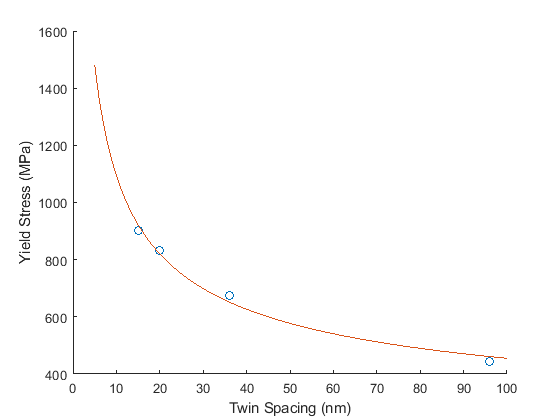

figure()
scatter(ts, sigma_0)
xlabel('Twin Spacing (nm)')
ylabel('Yield Stress (MPa)')
hold on
x = 5:1:100;
plot(x, sigma_int + kp*x.^-0.5)

% prediction
sigma_predicted = sigma_int + kp*7.^-0.5

sigma_predicted = 1.2762e+03

At 7 nm twin spacing, the predicted yield strength is 1276 MPa.

5.

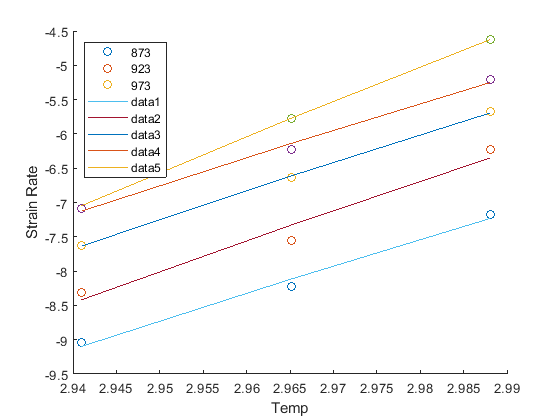

 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 0.000046 



clear all
% intialization
global s k i
k = 1.38e-23;                                           % boltzmann constant
s.stress_t = [200 250 300 350 390]*1e6.*ones(3,5);      % tensile stress
s.strain_rate = [9e-10 4.9e-9 2.4e-8 8.3e-8 NaN;        % measured strain rate
                6e-9 2.8e-8 2.3e-7 5.9e-7 1.7e-6;
                6.7e-8 5.9e-7 2.1e-6 6.3e-6 2.4e-5];
s.temp = [600; 650; 700]*ones(1,5) + 273;               % temperature of tests, converted to K

figure()
for i = 1:5
    scatter(log10(s.temp(:,i)), log10(s.strain_rate(:,i)))
    hold on
end
legend(num2str(s.temp(:,1)), 'Location','Northwest')
xlabel('Temp')
ylabel('Strain Rate')

% first determine Q by evaluating temperature dependence 
so = [-1e10,1e-19];
options = optimset('MaxFunEvals',1000000000);
for i = 1:5
    fit_params = fminsearch(@lsfitQ, so, options);
    Y = fit_params(1);              % y values are unimportant here, so save over
    q(i) = fit_params(2)/1.6e-19;
    plot(log10(s.temp(:,i)), log10(Y*exp((-q(i)*1.6e-19)./(k*s.temp(:,i)))))
    hold on
end

q

q =     3.1478    3.4893    3.2735    3.1634    4.0874


Although it was suggested to evaluate Q, the activation energy, with the temperature dependence at the lowest stress, it seemed important to check that the temperature dependence did not change over the range of stresses, which would suggest a change in mechanism, at least between Nabarro-Herring and Coble (NH to PLC would be undetectable here).  The Q-values obtained for each stress are very similar, save for the last one, which is not a good instance for linear regression anyways, with only two data points.

global Q
Q = q(1)

Q = 3.1478

Now that we have Q, we are able to use linear regression to effectively identify A via the stress dependence of the strain rate.

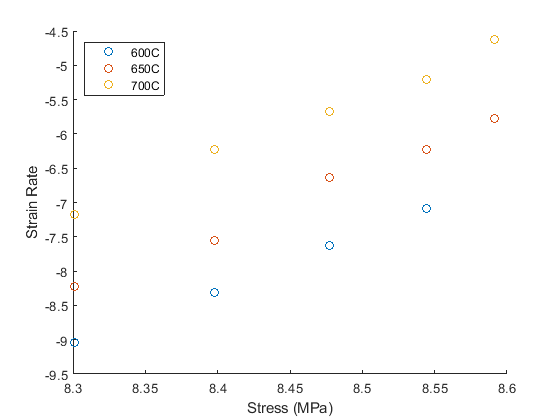

figure()
for j = 1:3
    scatter(log10(s.stress_t(j,:)), log10(s.strain_rate(j,:)))
    hold on
end
legend('600C', '650C', '700C', 'Location', 'Northwest')
xlabel('Stress (MPa)')
ylabel('Strain Rate')

At each temperature, the log-log plot appears to be linear, with a constant slope.  The slope should give an indication of what the stress exponent is.

dydx = [diff(log(s.strain_rate(1,:)))./diff(log(s.stress_t(1,:)));
    diff(log(s.strain_rate(2,:)))./diff(log(s.stress_t(2,:)));
    diff(log(s.strain_rate(3,:)))./diff(log(s.stress_t(3,:)))]

dydx =     7.5942    8.7144    8.0492       NaN
    6.9034   11.5503    6.1112    9.7794
    9.7490    6.9634    7.1269   12.3599


Diffusion-based mechanisms, (NH and Coble), have a stress exponent of about 1.  The stress exponents expected from PLC are in the range of 3 - 8.  

There are no distinct regimes, suggesting that the mechanism, PLC is conserved entirely.  This means we should be able to fit all data to one general creep equation.


figure()
global ji
for j = 1:3
    scatter(log10(s.stress_t(j,:)), log10(s.strain_rate(j,:)))
    hold on
end
legend('600C', '650C', '700C', 'Location', 'Northwest')
xlabel('Stress (MPa)')
ylabel('Strain Rate')
hold on
so = [5,1e10];
options = optimset('MaxFunEvals',1000000000);
fit_params = fminsearch(@lsfit5, so, options);
A = exp(fit_params(1))

A = 2.7680e-60

m = fit_params(2)

m = 8.2648

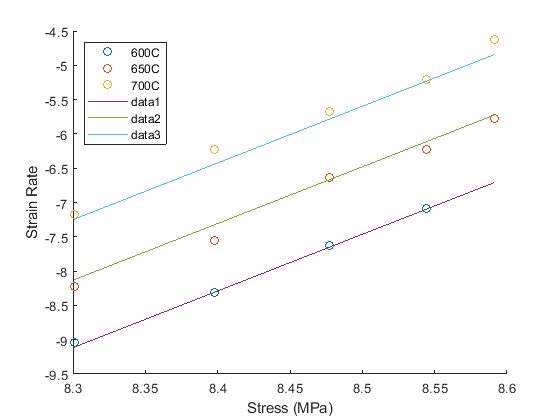

for ji = 1:3
    plot(log10(s.stress_t(ji,:)), log10(A*(s.stress_t(ji,:).^m).*exp(-(Q*1.6e-19)./(k*s.temp(ji,:)))))
    hold on
end

PLC has no grain size dependence.  Other diffusion-based creep mechanisms have a grain size dependence, allowing this as a means of differentiating between them. NH creep has a 1/d^2 dependence, Coble, 1/d^3.

% function defintions for linear regression

% linear regression Hall-Petch

function fits = lsfit4HP(so)
global sigma_0 ts
    fits = sum((sigma_0 - (so(1) + so(2)*ts.^-0.5)).^2);
end

% linear regression for q fit 
function fits = lsfitQ(so)
global s k i
    fits = nansum((log(s.strain_rate(:,i)) - (log(so(1)) - so(2)./(k*s.temp(:,i)))).^2);
end
% linear regression for A and m fit
function fits = lsfit5(so)
% does linear regression on all 3 lines at once, finding the best overall fit, assuming all lines have the same parameters
global s k Q
    fits = nansum((sum((log(s.strain_rate(:,:)) - (so(1) + so(2)*log(s.stress_t(:,:)) - (Q*1.6e-19)./(k*s.temp(:,:)))).^2)).^2);
end